close("all"); clear; clc;
sympref("FloatingPointOutput",false);

t = sym('t');
n = 5;
f = @(n)legpol(n)*t.^(fliplr(0:n).');
T = arrayfun(f,(1:n).')

$$T = \left[\begin{array}{c} t\\ \frac{3\,t^{2}}{2}-\frac{1}{2}\\ \frac{5\,t^{3}}{2}-\frac{3\,t}{2}\\ \frac{35\,t^{4}}{8}-\frac{15\,t^{2}}{4}+\frac{3}{8}\\ \frac{63\,t^{5}}{8}-\frac{35\,t^{3}}{4}+\frac{15\,t}{8} \end{array}\right]$$

fT = matlabFunction(T);
ns = 100;
t = linspace(-1,1,ns);
f = fT(t);

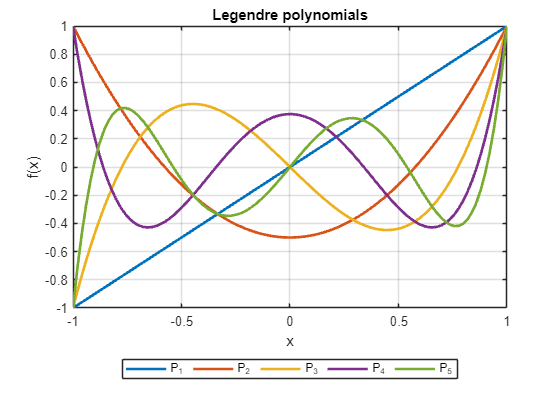

fig = figure();
hold("on");
for i = 1:n
    plot(t,f(i,:),"LineWidth",2);
end
hold("off");
box("on");
grid("on");
leg_names = arrayfun(@(i)"P_" + i,1:n,"UniformOutput",false);
legend(leg_names{:}, ...
    "Location","SouthOutside", ...
    "Orientation","Horizontal");
title("Legendre polynomials");
xlabel("x");
ylabel("f(x)")